load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

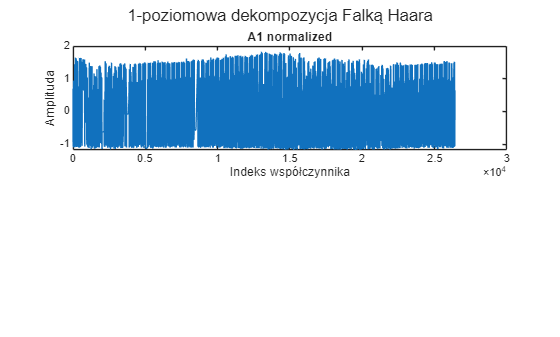

function results_py = model_hybrid(y_train, y_test, step_length, season_period)
    py_model = py.importlib.import_module("HoltWintersModule");
    results_py = py_model.forecast_holt_winters(...
        y_train,...
        y_test,...
        step_length,...
        season_period ...
        ).double;
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[A1_norm, center_A1, scale_A1] = normalize(A1);

% 2. RYSOWANIE WYKRESÓW
figure;

subplot(2, 1, 1);
plot(A1_norm);
title('A1 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

sgtitle('1-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
A1_test_norm = (A1_test - center_A1) ./ scale_A1;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

dlugosc_testu_A1 = ceil(dlugosc_testu_oryginalna / 2);

% Przewidywania A1 - model hybrydowy
A1_pred_norm = model_hybrid(A1_norm, A1_test_norm(1:dlugosc_testu_A1), 1, 96);

Rozpoczynanie prognozy (Refitting Expanding Window)...
Rozmiar testowy: 1440, Krok: 1, Pętle: 1440
  Pętla 1/1440 (Rozmiar danych tren.: 26399)...
  Pętla 2/1440 (Rozmiar danych tren.: 26400)...
  Pętla 3/1440 (Rozmiar danych tren.: 26401)...
  Pętla 4/1440 (Rozmiar danych tren.: 26402)...
  Pętla 5/1440 (Rozmiar danych tren.: 26403)...
  Pętla 6/1440 (Rozmiar danych tren.: 26404)...
  Pętla 7/1440 (Rozmiar danych tren.: 26405)...
  Pętla 8/1440 (Rozmiar danych tren.: 26406)...
  Pętla 9/1440 (Rozmiar danych tren.: 26407)...
  Pętla 10/1440 (Rozmiar danych tren.: 26408)...
  Pętla 11/1440 (Rozmiar danych tren.: 26409)...
  Pętla 12/1440 (Rozmiar danych tren.: 26410)...
  Pętla 13/1440 (Rozmiar danych tren.: 26411)...
  Pętla 14/1440 (Rozmiar danych tren.: 26412)...
  Pętla 15/1440 (Rozmiar danych tren.: 26413)...
  Pętla 16/1440 (Rozmiar danych tren.: 26414)...
  Pętla 17/1440 (Rozmiar danych tren.: 26415)...
  Pętla 18/1440 (Rozmiar danych tren.: 26416)...
  Pętla 19/1440 (Rozmiar dan

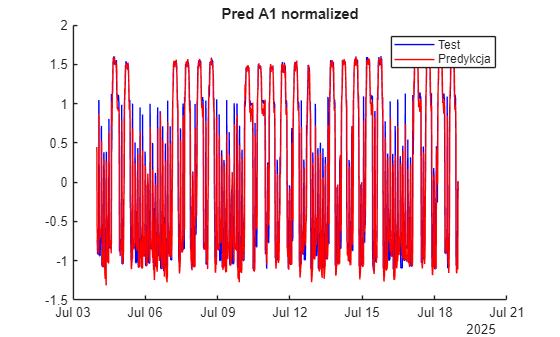

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A1), A1_test_norm(1:dlugosc_testu_A1), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(A1_pred_norm)), A1_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

% DENORMALIZACJA
A1_pred = (A1_pred_norm .* scale_A1) + center_A1;

D1_pred = zeros(length(A1_pred),1)';

final_prediction = idwt(A1_pred, D1_pred,'haar');      % podejście: A1 Holt Winters

y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction)

mae_score = 0.0947

mape_score = mape(y_test, final_prediction)

mape_score = 170.1928

rmse_score = rmse(y_test, final_prediction)

rmse_score = 0.1755

r2_classic = R2_classic(y_test, final_prediction)

r2_classic = 0.7431

r2_alt = R2_alt(y_test, final_prediction)

r2_alt = 0.9225

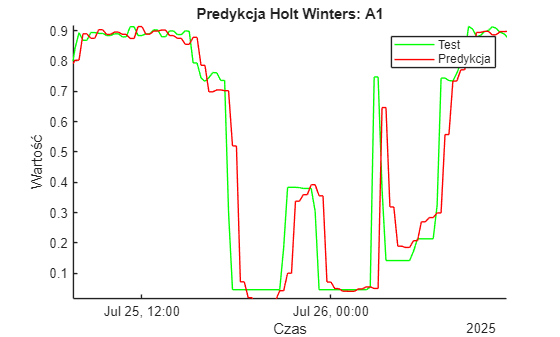


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(final_prediction)), ab_diff_test_norm(1:length(final_prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(final_prediction)), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   final_prediction(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_A1_HW_1_month.xlsx');